% F-16 lateral regulator
% JSH 3/9/20
clear all global;

% Plant dynamics
A =[-0.322 0.0640 0.0364 -0.9917 0.0003 0.0008 0;       % x1 = beta
    0 0 1 0.0037 0 0 0;                                 % x2 = phi
    -30.6492 0 -3.6784 0.6646 -0.7333 0.1315 0;         % x3 = p
    8.5396 0 -0.0254 -0.4764 -0.0319 -0.0620 0;         % x4 = r
    0 0 0 0 -20.2 0 0;                                  % x5 = delta_a
    0 0 0 0 0 -20.2 0;                                  % x6 = delta_r
    0 0 0 57.2958 0 0 -1];                              % x7 = x_w

B = [0 0; 
    0 0; 
    0 0; 
    0 0; 
    20.2 0; 
    0 20.2; 
    0 0];          % u1 = delta_a (aileron)
                   % u2 = delta_r (rudder)
C = [0 0 0 57.2958 0 0 -1;                              % y1 = r_w (washed out yaw rate)
    0 0 57.2958 0 0 0 0;                                % y2 = p
    57.2958 0 0 0 0 0 0;                                % y3 = beta
    0 57.2958 0 0 0 0 0];                               % y4 = phi
   
D = zeros(4,2);

% Static feedback controller u = -Ky
K = [-0.56 -0.44 -0.11 -0.35; 
    -1.19 -0.21 -0.44 0.26];

G = minreal(ss(A, B, C, D));
L = G * K;
So = (eye(4) + L)^-1;
To = L * So;

s = tf('s');
A = 4;
M = 10;
wb = 3;
tau = 0.02;
r0 = 0.05;
rinf = 0.4;
Wo = eye(4) * ((tau * s) + r0) / ((tau * s / rinf) + 1);
Wp = eye(4) * ((s/M) + wb) / (s + (wb*A));

% Nominal Performance
Nominal_Performance = norm(Wp * To, 'inf')

Nominal_Performance = 0.8292


%  Robust Stability
Robust_Stability = norm(Wo * So, 'inf')

Robust_Stability = 0.5076

u0 = 0.4 * 1126;
Yr = 0;
Nr = -0.639;
Nbeta = 15.16;
Ybeta = -110.94;
Ndela = 0.334;
Ydelr = 19.65;
Ndelr = -6.732;

A = [(Ybeta/u0) -(1-(Yr/u0)); Nbeta Nr];
B = [0 Ydelr/u0; Ndela Ndelr];
C = eye(2);
D = 0;

G = ss(A,B,C,D)

G =
 
  A = 
            x1       x2
   x1  -0.2463       -1
   x2    15.16   -0.639
 
  B = 
            u1       u2
   x1        0  0.04363
   x2    0.334   -6.732
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.




M = 2;
A = 0.005;
wb = 1;
Wp = eye(2) * ((s/M)+wb) / (s+(wb*A));

systemnames = 'G Wp';
inputvar = '[w(2); u(2)]';
outputvar = '[Wp; -G-w]';
input_to_G = '[u]';
input_to_Wp = '[G+w]';
sysoutname = 'P';
sysic;

[K,CL,GAM,info] = hinfsyn(P, 1, 1, 'method', 'ric', 'Tolgam', 1e-3, 'DISPLAY', 'on');


  Test bounds:  200.1 <=  gamma  <=  213.3

    gamma        X>=0        Y>=0       rho(XY)<1    p/f
  2.066e+02     1.5e-06     0.0e+00     1.710e-02     p
  2.033e+02     1.5e-06     0.0e+00     1.953e-02     p
  2.017e+02     1.5e-06     0.0e+00     2.143e-02     p
  2.009e+02     1.5e-06     0.0e+00     2.286e-02     p
  2.005e+02     1.5e-06     6.0e-13     2.392e-02     p
  2.003e+02     1.5e-06     1.0e-12     2.469e-02     p
  2.002e+02     1.5e-06     0.0e+00     2.523e-02     p
  Limiting gains...
  2.003e+02     1.5e-05     1.9e-13     2.469e-02     p
  2.003e+02     1.5e-04     1.9e-13     2.470e-02     p
  2.003e+02     1.5e-03     1.9e-13     2.472e-02     p
  2.003e+02     1.3e-02     1.9e-13     2.516e-02     p
  2.003e+02     1.2e-01     1.9e-13     3.903e-02     p
  2.003e+02     2.2e-01     1.9e-13     1.908e-01     p
  2.003e+02     2.2e-01     1.9e-13     6.674e-01     p
  2.003e+02     2.2e-01     1.9e-13     8.961e-01     p

  Best performance (actual): 200.1


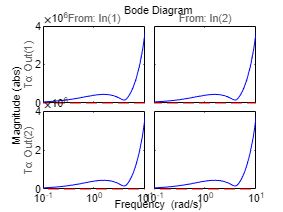

L = G * K;
So = (eye(1)+L)^-1;
To = L * So;

figure
linMagopt = bodeoptions;
linMagopt.PhaseVisible = 'off';
linMagopt.XLim = [1e-1 1e1];
linMagopt.MagUnits = 'abs';

bodeplot(inv(Wp), 'r--', So, 'b-', linMagopt);

% h = sigmaplot(So, 'b-');
% setoptions(h,'MagUnits','abs');